% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 3;
avgNum = 3;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/Growth_2/";
file_name = "Growth_2024-06-21_40000_10_2024-06-21-15.43.12.430.csv";
file_path = data_path+file_name;

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Read the CSV file, skipping the metadata rows
growth_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth2_2024-06-21_40000_10_2024-06-21-15.54.35.897.csv";
file_path = strcat(data_path,file_name);
growth_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth3_2024-06-21_40000_10_2024-06-21-16.05.57.603.csv";
file_path = strcat(data_path,file_name);
growth_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth4_2024-06-21_40000_10_2024-06-21-16.16.10.013.csv";
file_path = strcat(data_path,file_name);
growth_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Silicon_2024-06-21_300_100_2024-06-21-15.08.55.127.csv";
file_path = strcat(data_path,file_name);
silicon_ref = readmatrix(file_path);

file_name = "Polystyrene_2024-06-21_400_100_2024-06-21-15.14.19.860.csv";
file_path = strcat(data_path,file_name);
polystyrene_ref = readmatrix(file_path);

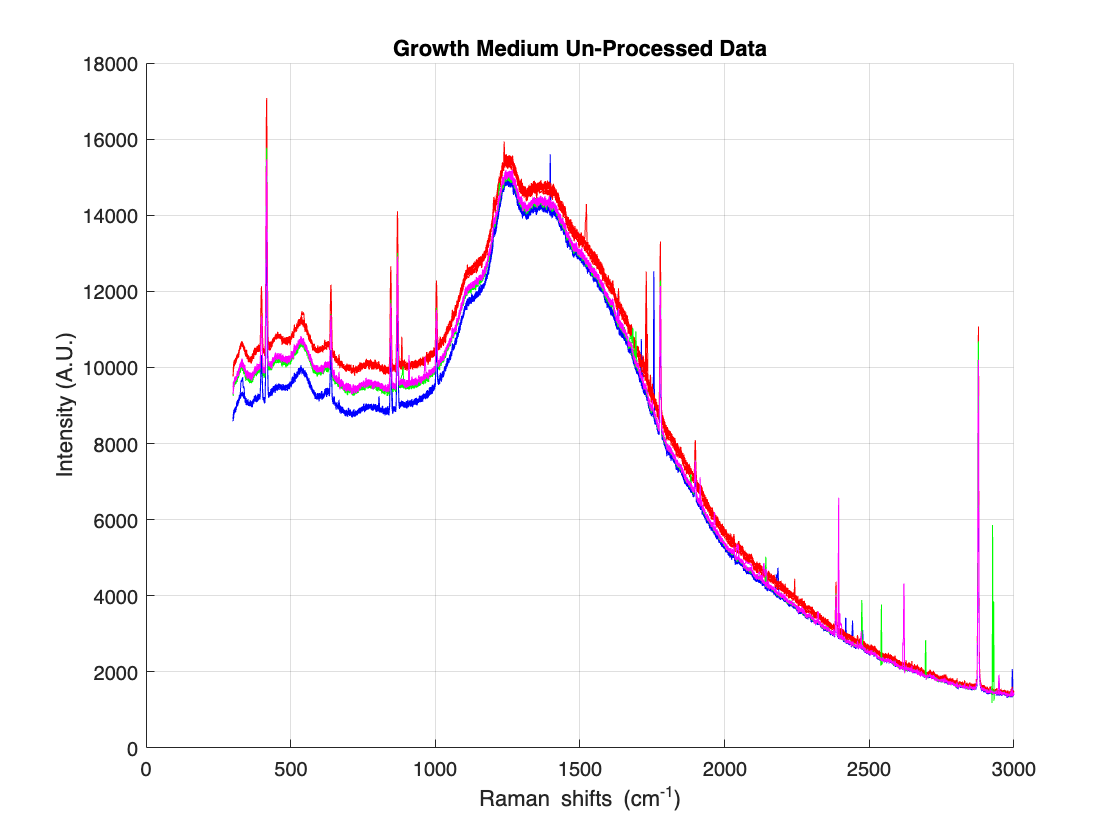

% Configuring and plotting unprocessed data

wavenumber = silicon_ref(1,:);
grow4 = growth_4;
silref = silicon_ref;
polyref = polystyrene_ref;
grow1 = growth_1;
grow2 = growth_2;
grow3 = growth_3;

% trimming standard sample data to these WN's
t1 = 300;
t2 = 3000;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
grow4(:, grow4(1, :) <= t1) = [];
grow4(:, grow4(1, :) >= t2) = [];
silref(:, silref(1, :) <= t1) = [];
silref(:, silref(1, :) >= t2) = [];
polyref(:, polyref(1, :) <= t1) = [];
polyref(:, polyref(1, :) >= t2) = [];
grow1(:, grow1(1, :) <= t1) = [];
grow1(:, grow1(1, :) >= t2) = [];
grow2(:, grow2(1, :) <= t1) = [];
grow2(:, grow2(1, :) >= t2) = [];
grow3(:, grow3(1, :) <= t1) = [];
grow3(:, grow3(1, :) >= t2) = [];

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, grow1(2:end, :), '-b');
plot(wavenumber, grow2(2:end, :), '-r');
plot(wavenumber, grow3(2:end, :), '-g');
plot(wavenumber, grow4(2:end, :), '-m');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Un-Processed Data');
hold off;

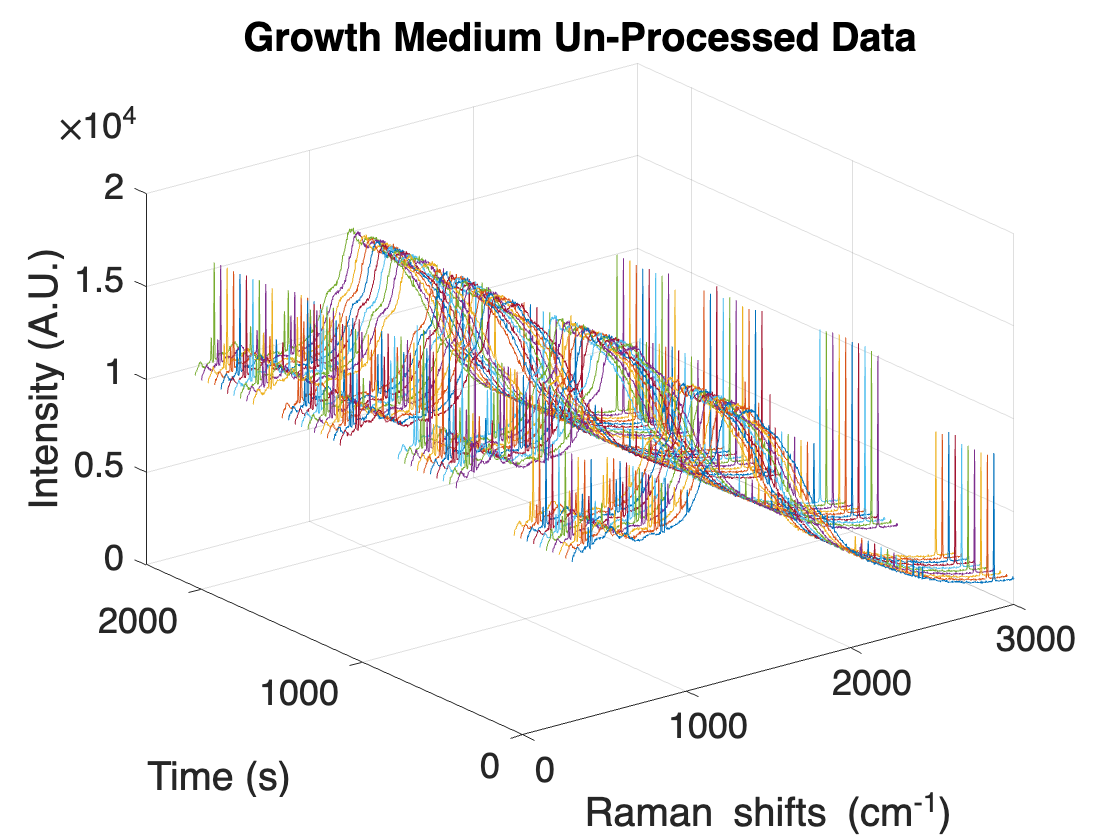

% Plotting time scale for each spectra

time1 = [0, 40, 80, 120, 160, 200, 240, 280, 320, 360, 400];
time2 = time1+720;
time3 = time1+1440;
time4 = time1+1980;

fig2 = figure;
ax2 = axes(fig2);
hold on;
grid on;

plot3(wavenumber, time1(1) * ones(size(wavenumber)), grow1(2,:), '-');
plot3(wavenumber, time1(2) * ones(size(wavenumber)), grow1(3,:), '-');
plot3(wavenumber, time1(3) * ones(size(wavenumber)), grow1(4,:), '-');
plot3(wavenumber, time1(4) * ones(size(wavenumber)), grow1(5,:), '-');
plot3(wavenumber, time1(5) * ones(size(wavenumber)), grow1(6,:), '-');
plot3(wavenumber, time1(6) * ones(size(wavenumber)), grow1(7,:), '-');
plot3(wavenumber, time1(7) * ones(size(wavenumber)), grow1(8,:), '-');
plot3(wavenumber, time1(8) * ones(size(wavenumber)), grow1(9,:), '-');
plot3(wavenumber, time1(9) * ones(size(wavenumber)), grow1(10,:), '-');
plot3(wavenumber, time1(10) * ones(size(wavenumber)), grow1(11,:), '-');

plot3(wavenumber, time2(1) * ones(size(wavenumber)), grow2(2,:), '-');
plot3(wavenumber, time2(2) * ones(size(wavenumber)), grow2(3,:), '-');
plot3(wavenumber, time2(3) * ones(size(wavenumber)), grow2(4,:), '-');
plot3(wavenumber, time2(4) * ones(size(wavenumber)), grow2(5,:), '-');
plot3(wavenumber, time2(5) * ones(size(wavenumber)), grow2(6,:), '-');
plot3(wavenumber, time2(6) * ones(size(wavenumber)), grow2(7,:), '-');
plot3(wavenumber, time2(7) * ones(size(wavenumber)), grow2(8,:), '-');
plot3(wavenumber, time2(8) * ones(size(wavenumber)), grow2(9,:), '-');
plot3(wavenumber, time2(9) * ones(size(wavenumber)), grow2(10,:), '-');
plot3(wavenumber, time2(10) * ones(size(wavenumber)), grow2(11,:), '-');

plot3(wavenumber, time3(1) * ones(size(wavenumber)), grow3(2,:), '-');
plot3(wavenumber, time3(2) * ones(size(wavenumber)), grow3(3,:), '-');
plot3(wavenumber, time3(3) * ones(size(wavenumber)), grow3(4,:), '-');
plot3(wavenumber, time3(4) * ones(size(wavenumber)), grow3(5,:), '-');
plot3(wavenumber, time3(5) * ones(size(wavenumber)), grow3(6,:), '-');
plot3(wavenumber, time3(6) * ones(size(wavenumber)), grow3(7,:), '-');
plot3(wavenumber, time3(7) * ones(size(wavenumber)), grow3(8,:), '-');
plot3(wavenumber, time3(8) * ones(size(wavenumber)), grow3(9,:), '-');
plot3(wavenumber, time3(9) * ones(size(wavenumber)), grow3(10,:), '-');
plot3(wavenumber, time3(10) * ones(size(wavenumber)), grow3(11,:), '-');

plot3(wavenumber, time4(1) * ones(size(wavenumber)), grow4(2,:), '-');
plot3(wavenumber, time4(2) * ones(size(wavenumber)), grow4(3,:), '-');
plot3(wavenumber, time4(3) * ones(size(wavenumber)), grow4(4,:), '-');
plot3(wavenumber, time4(4) * ones(size(wavenumber)), grow4(5,:), '-');
plot3(wavenumber, time4(5) * ones(size(wavenumber)), grow4(6,:), '-');
plot3(wavenumber, time4(6) * ones(size(wavenumber)), grow4(7,:), '-');
plot3(wavenumber, time4(7) * ones(size(wavenumber)), grow4(8,:), '-');
plot3(wavenumber, time4(8) * ones(size(wavenumber)), grow4(9,:), '-');
plot3(wavenumber, time4(9) * ones(size(wavenumber)), grow4(10,:), '-');
plot3(wavenumber, time4(10) * ones(size(wavenumber)), grow4(11,:), '-');

xlabel(ax2, 'Raman shifts (cm^{-1})');
ylabel(ax2, 'Time (s)');
zlabel(ax2, 'Intensity (A.U.)');
title('Growth Medium Un-Processed Data');
ax2.FontSize = 18;
view(3);

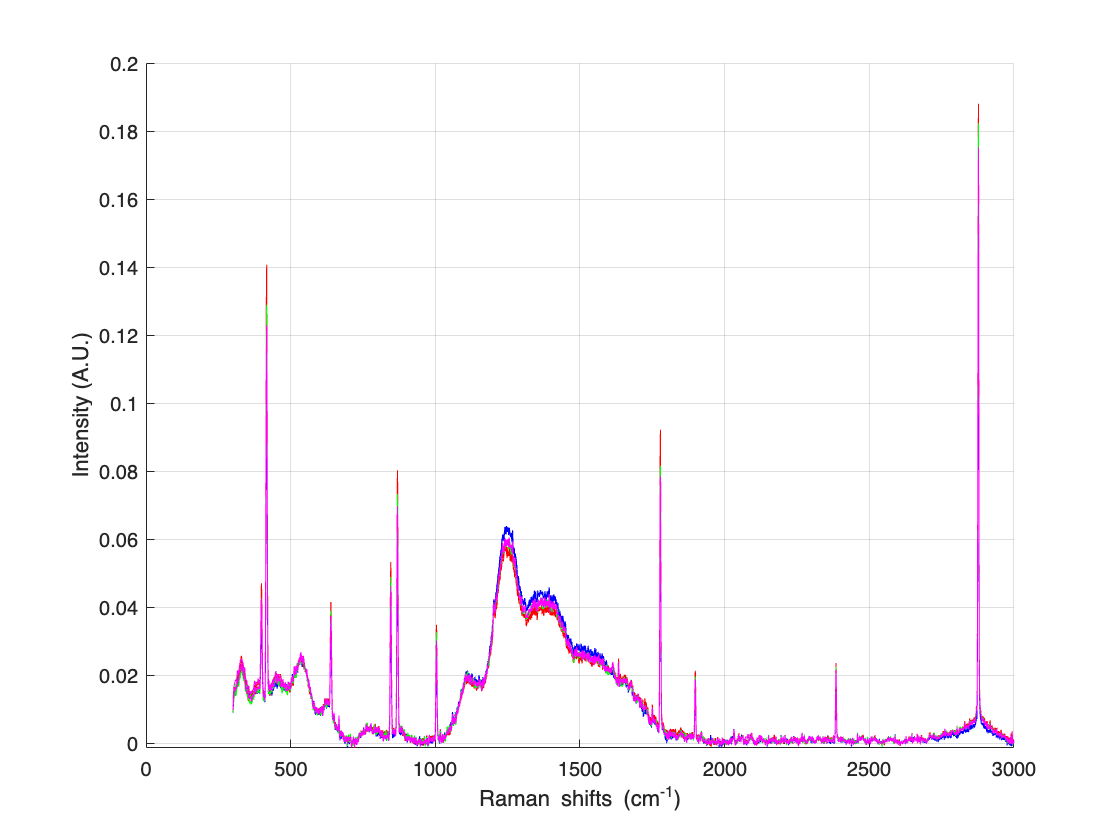

% Preprocessing the data

pro_grow4 = apply(grow4, [6,1,8,2,5,6,7]);
pro_silref = apply(silref, [6,1,8,5,6,7]);
pro_polyref = apply(polyref, [6,1,8,5,6,7]);

pro_grow1 = apply(grow1, [6,1,8,2,5,6,7]);
pro_grow2 = apply(grow2, [6,1,8,2,5,6,7]);
pro_grow3 = apply(grow3, [6,1,8,2,5,6,7]);

time = [0, 720, 1440, 1980];

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_grow1, '-b');
plot(wavenumber, pro_grow2, '-r');
plot(wavenumber, pro_grow3, '-g');
plot(wavenumber, pro_grow4, '-m');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

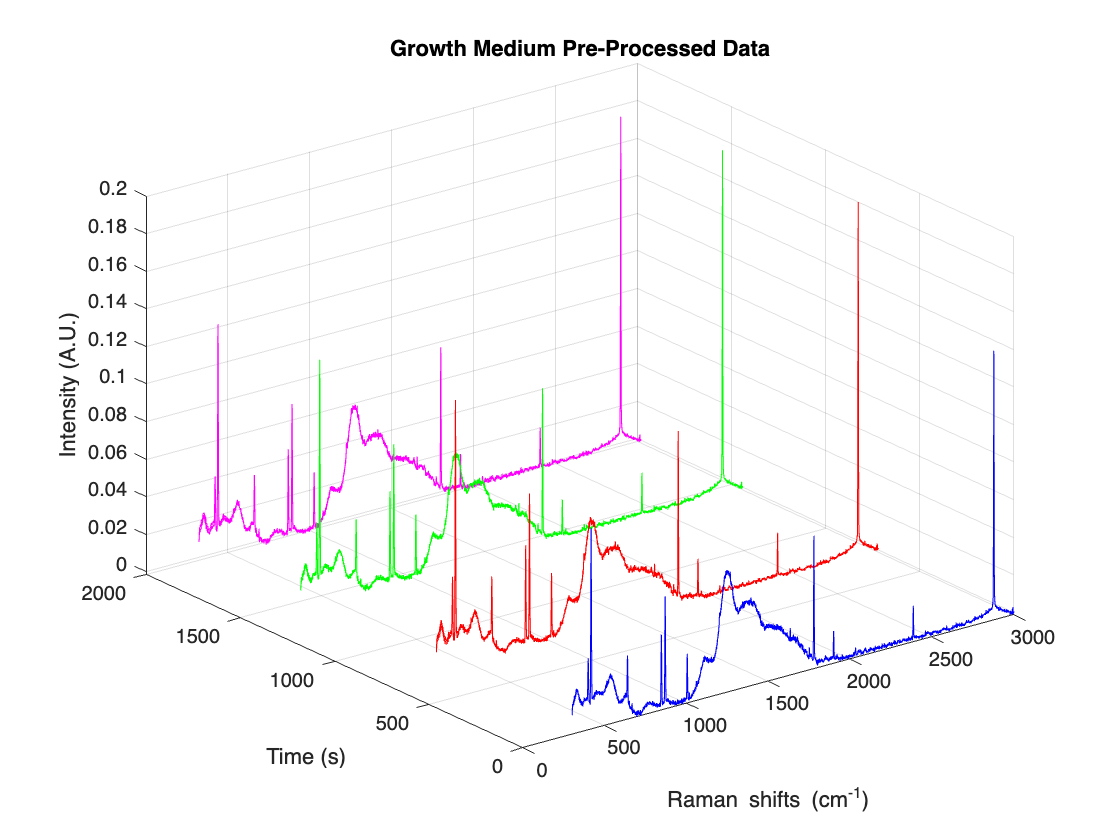


figure;
hold on;
grid on;
plot3(wavenumber, time(1) * ones(size(wavenumber)), pro_grow1, '-b');
plot3(wavenumber, time(2) * ones(size(wavenumber)), pro_grow2, '-r');
plot3(wavenumber, time(3) * ones(size(wavenumber)), pro_grow3, '-g');
plot3(wavenumber, time(4) * ones(size(wavenumber)), pro_grow4, '-m');
xlabel('Raman shifts (cm^{-1})');
ylabel('Time (s)');
zlabel('Intensity (A.U.)');
title('Growth Medium Pre-Processed Data');
view(3);


% figure;
% hold on;
% grid on;
% plot(wavenumber, pro_grow4, '-b');
% plot(wavenumber, pro_silref, '-r');
% plot(wavenumber, pro_polyref, '-g');
% xlabel('Raman shifts (cm^{-1})')
% ylabel('Intensity (A.U.)')
% hold off;

% Finding peak variance (521cm^-1)
% 
% A = [pro_grow4(:,321);pro_silref(:,321);pro_polyref(:,321)];
% 
% av = mean(A)
% std = var(A)
% CV = sqrt(std)/av

% % ANOVA test for Polystyrene
% 
% % Reformat the intensity data into a single column
% intensities_poly = [pro_poly1(:); pro_poly2(:); pro_poly3(:)];
% 
% % Create a wavenumber label for each intensity reading
% wavenumbers = repmat(wavenumber(:), 6 * 3, 1);  % wavenumber repeated for each intensity reading
% 
% % Create a grouping variable for day
% days = [repmat({'May 15'}, numel(pro_poly1), 1); 
%         repmat({'May 16'}, numel(pro_poly2), 1); 
%         repmat({'May 17'}, numel(pro_poly3), 1)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_poly, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});
% disp('Polystyrene ANOVA Table:');
% disp(tbl);

% % ANOVA test for Silicon
% 
% % Reformat the intensity data into a single column
% intensities_sil = [pro_sil1(:); pro_sil2(:); pro_sil3(:)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_sil, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});
% disp('Silicon ANOVA Table:');
% disp(tbl);

% figure; % Create a new figure for the box plot
% boxplot(intensities_poly, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Polystyrene');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 15', 'May 16', 'May 17'});
% 
% figure; % Create a new figure for the box plot
% boxplot(intensities_sil, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Silicon');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 15', 'May 16', 'May 17'});

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end
